# Basis Functions

## Introduction

The standard basis functions used in the Finite Element Method are low-order $C^0$-continuous basis functions. Low-order means that their polynomial dergee is kept low, whereas $C^0$-continuous means that they are continuous with discontinuous derivatives across element boundaries. Moreover, the standard low-order $C^0$-continuous basis functions are typically supported within the elements that contain the nodes associated with them. An example of the two-dimensional basis functions constructed using the Lagrange Polynomials is shown in the following figure,

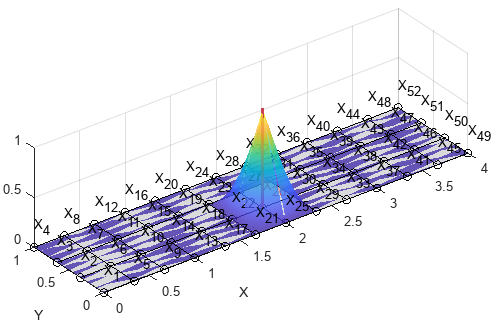

In this figure it can be seen that the basis function assosicated with node $X_{22}$ that takes the value 1.0 at that node, is supported only in the elements containing node $X_{22}$ whereas it is zero everywhere else. Note that the function is only $C^0$-continuous.

These kinds of basis functions are constructed to be interpolatory by nature at the nodes. This means that the nodal solutions obtained by such discretizations represent the sought field at these locations. The construction of interpolatory basis functions can be optimally achieved using the so-called [Lagrange Polynomials](https://en.wikipedia.org/wiki/Lagrange_polynomial). The Lagrange Polynomials can be used to construct interpolatory basis functions at the element level.

The construction of higher-dimensional basis functions (2D, 3D, etc.) based on the Lagrange Polynomials can be achieved by tensor product of the one-dimensional Lagrange Polynomials. The Lagrange Polynomials naturally define a mapping between a parametric and the physical space $\mathbf{\xi} \rightarrow \mathbf{X}$.

It is extensively used the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html)™ in [MATLAB](https://www.mathworks.com/products/matlab.html)® for the setup and visualization of the underlying expressions.

[NEXT](matlab:open('..\2_TimoshenkoBeam\main_Chapter2_ALinearStraightTimoshenkoBeamElement.mlx')) Chapter *Finite Element Formulation of the linear Timoshenko beam*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

### Clear command window, workspace and close all figures

clc;
clear;
close all;

## One-dimensional linear basis functions

### One-dimensional linear mesh

X-coordinate at the left edge of the one-dimensional domain $\left\lbrack 0,L\right\rbrack$

X0L1 = 0;

X-coordinate at the right edge of the one-dimensional domain $\left\lbrack 0,L\right\rbrack$

XLL1 = 4;

Number of elements for the linear one-dimensional mesh

numElementsL1 = 4;

Mesh generation

mshL1 = generateLinearMeshOnLine(X0L1, XLL1, numElementsL1);

### Construction of the basis functions

Navigate to [THIS](matlab:open('./main_Chapter11_OneDimensionalLinearBasisFunctions.mlx')) section

evalc('main_Chapter11_OneDimensionalLinearBasisFunctions');

### Geometry interpolation


$$x(\xi) = \sum_{i =1}^2 N_i (\xi) X_i$$


#### Element by id

elL1 = 2;

#### Parametric location by coordinate

xiL1 =-0.64;

  **Try**

Change the parametric location using variable `xiL1` and observe the resulting figures for different values.

 **Reflect**

Is the value of the Jacobian affected by these changes of the parametric location and why?

Display the basis functions and their values at the selected parametric location, the physical image of the selected parametric location and the Jacobian of the geometry parametrization on the selected parametric location

t1 = plot1dMeshAndGeometryMapping(elL1, xiL1, mshL1, NL1);

## One-dimensional quadratic basis functions

### One-dimensional quadratic mesh

mshL2 = generateQuadraticMeshOnLine(mshL1);

### Construction of the basis functions

Navigate to [THIS](matlab:open('./main_Chapter12_OneDimensionalQuadraticBasisFunctions.mlx')) section

evalc('main_Chapter12_OneDimensionalQuadraticBasisFunctions');

### Geometry interpolation


$$x(\xi) = \sum_{i =1}^3 l_i (\xi) X_i$$


#### Parametric location by coordinate

xiL2 =0.3;

#### Deviation of the mid-node with respect to the middle of the element

dev = -0.2;

  **Try**

Move the mid-node in the physical space of the element away from the middle of the element

 **Reflect**

What happens to the Jacobian of the geometry parametrization when the mid-node of the finite element is not at the mid-distance between the corner nodes and why?

#### Element by id

elL2 = 2;

#### Displacement of the mid-node of the element based on the chosen deviation

mshL2Mod = mshL2;
nodesElL2 = mshL2Mod.elements(elL2, :);
mshL2Mod.nodes(nodesElL2(2), 1) = mean(mshL2.nodes(nodesElL2([1 3]))) + dev;

#### Visualization of the basis functions, their values in the chosen parametric location, the physical location of the chosen parametric location, the distribution of the determinant of the Jacobian and its value at the chosen parametric location

plot1dMeshAndGeometryMapping(elL2, xiL2, mshL2Mod, NL2);

## Two-dimensional bilinear basis functions

### Two-dimensional bilinear mesh

#### Definition of the rectangular domain

X0 = 1.25;
XLx = X0 + 2.31;
Y0 = 2.15;
YLy = Y0 + 0.82;

#### Definition of the number of elements in the Cartesian domain

numElx = 3;
numEly = 2;
numEl = numElx*numEly;

#### Generate a bilinear quadrilateral mesh

figure
numNodesElQ1 = 4;
[nodesX, nodesY] = generateQuadrilateralMesh(X0, XLx, Y0, YLy, numElx, numEly);
mshQ1 = generateBilinearQuadrilateralMesh ...
    (numElx, numEly, numEl, nodesX, nodesY, numNodesElQ1);
numNodes_Q1 = numel(mshQ1.nodes(:, 1));
numVertices = numel(mshQ1.nodes(:, 1));
ij = ["1,1", "1,2", "2,2", "2,1"];

### Construction of the basis functions

Navigate to [THIS](matlab:open('./main_Chapter13_TwoDimensionalBilinearBasisFunctions.mlx')) section

evalc('main_Chapter13_TwoDimensionalBilinearBasisFunctions');

### Geometry interpolation


$$\mathbf{X}(\xi, \eta) = \sum_{i =1}^2 \sum_{j =1}^2 l_{i,j} (\xi, \eta) \mathbf{X}_{i,j}$$


#### Choice of element

elQ1 = 3;

#### Choice of parametric location

xiQ1 = -0.2;
etaQ2 = 0.3;

  **Try**

Change the parametric locations using variables `xiQ1` and `etaQ1`, and observe the resulting figures for different values.

 **Reflect**

- Is the value of the Jacobian affected by these changes of the parametric location and why?

- How can you render the Jacobian for this element non-constant? Perform the necessary change and try again modifying the values for `xiQ1` and `etaQ1`

#### Visualization of the basis functions, their values in the chosen parametric location, the physical location of the chosen parametric location, the distribution of the determinant of the Jacobian and its value at the chosen parametric location

plotBilinearQuadrilateralMeshAndGeometryMapping ...
    (xiQ1, etaQ2, elQ1, lijQ1, ij, mshQ1, numVertices);

## Two-dimensional biquadratic basis functions

### Two-dimensional biquadratic mesh

#### Definition of the rectangular domain

X0 = 1.25;
XLx = X0 + 2.31;
Y0 = 2.15;
YLy = Y0 + 0.82;

#### Definition of the number of elements

numElx = 3;
numEly = 2;
numEl = numElx*numEly;

#### Generation of a bilinear quadrilateral mesh

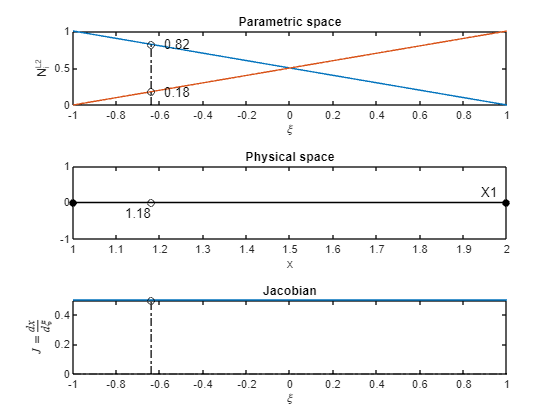

figure,
numNodesElQ1 = 4;

mshQ1 = generateBilinearQuadrilateralMesh ...
    (numElx, numEly, numEl, nodesX, nodesY, numNodesElQ1);
numNodesEl_Q2 = 9;
[mshQ2, ~] = generateBiquadraticQuadrilateralMesh ...
    (numElx, numEly, nodesX, nodesY, mshQ1, numNodesElQ1, numNodesEl_Q2);
numVerticesQ2 = numel(mshQ2.nodes(:, 1));
plotMesh2d(mshQ2, numVerticesQ2, true);
axis equal;
xlabel("$X$", Interpreter="latex")
ylabel("$Y$", Interpreter="latex")
zlabel("$Z$", Interpreter="latex")

### Construction of the basis functions

Navigate to [THIS](matlab:open('./main_Chapter14_TwoDimensionalBiquadraticBasisFunctions.mlx')) section

evalc('main_Chapter14_TwoDimensionalBiquadraticBasisFunctions');

### Geometry interpolation


$$\mathbf{X}(\xi, \eta) = \sum_{i =1}^3 \sum_{j =1}^3 l_{i,j} (\xi, \eta) \mathbf{X}_{i,j}$$


#### Choice of the parametric location where to compute the basis functions and its physical image

xiQ2 = 1;
etaQ2 = 0;

#### Choice of the deviation of the mid-node with respect to the middle of the element

devX = 0;
devY = 0;
mshQ2Mod = mshQ2;
nodesElQ2 = mshQ2Mod.elements(elQ2, :);
mshQ2Mod.nodes(nodesElQ2(9), 1:2) = mean(mshQ2.nodes(nodesElQ2(1:8), 1:2)) + ...
    [devX devY];

  **Try**

Change the parametric locations using variables `xiQ2` and `etaQ2`, and observe the resulting figures for different values

 **Reflect**

- Is the value of the Jacobian affected by these changes of the parametric location and why?

#### Visualization of the basis functions, their values in the chosen parametric location, the physical location of the chosen parametric location, the distribution of the determinant of the Jacobian and its value at the chosen parametric location

plotBiquadraticQuadrilateralMeshAndGeometryMapping ...
    (xiQ2, etaQ2, elQ2, lijQ2, mshQ2Mod, numVertices, ijQ2);

## References

[[1] Hughes, Thomas JR. *The finite element method: linear static and dynamic finite element analysis*. Courier Corporation, 2012.](https://doi.org/10.1111/j.1467-8667.1989.tb00025.x)

## **Helper functions**

### **Display a two-dimensional bilinear quadrilateral mesh along with the geometric mapping at a selected parametric location**

function t = plotBilinearQuadrilateralMeshAndGeometryMapping ...
    (xi_, eta_, el, lijQ1, ij, msh, numVertices)

**Function description**

Plots a graph displaying the basis functions and their values in the chosen parametric location corresponding to a two-dimensional bilinear quadrilateral mesh. Moreover, the physical image and the determinant of the Jacobian at the selected parametric location is displayed.

**             Input :**

         xi_,eta_ : The selected parametric locations on the element

                   el : The selected element

             lij_Q1 : The two-dimensional bilinear Lagrange Polynomials in the parametric space

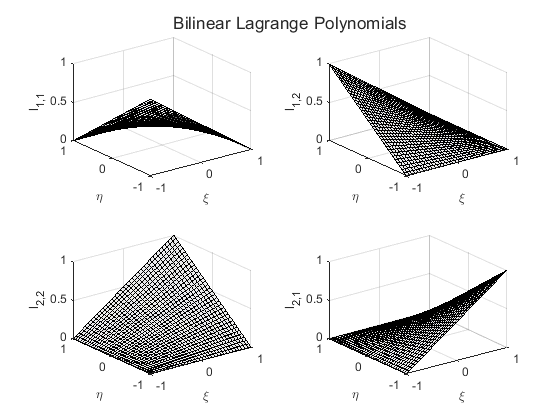

               `X_Q1` : The position vector of the geometry parametrization

                 `msh` : A two-dimensional four-noded mesh as a structure with the following fields:

                            `.nodes` : Number of nodes in the two-dimensional mesh

                       `.elements` : Number of elements in the two-dimensional mesh

 `numVertices` : Number of vertices in the bilinear quadrilateral mesh

                   `ij` : Legend entries for the plot which should be an array with four elements

**          Output :**

                    `t` : Handle to the tiledlayout graphical object

**Function implementation**

Read input

    if ~ismember(el, 1:numel(msh.elements(:, 1)))
        error("The selected element does not belong to the provided mesh");
    end

#### Set-up the geometric interpolation

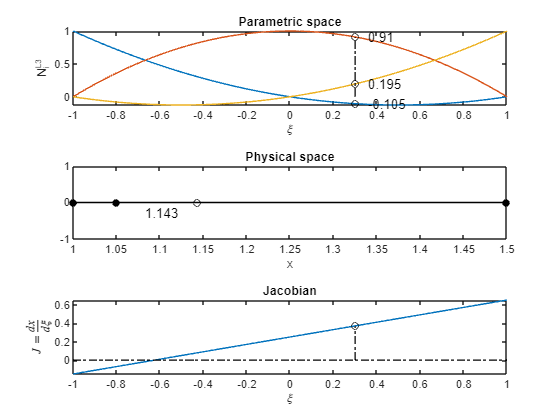

    syms X_Q1(xi, eta)

    X_Q1(xi, eta) = transpose([lijQ1{:}]*msh.nodes(msh.elements(el, :), 1:3));

Display the basis functions and their values at the selected parametric location

    t = tiledlayout(2, 2);
    for ii = 1:numel(lijQ1)
        nexttile
        fsurf(lijQ1{ii}, [-1 1 -1 1], "FaceColor", [217, 218, 219]./255, ...
            "FaceAlpha", 0.5);
        hold on;
        plot3(xi_, eta_, lijQ1{ii}(xi_, eta_), "ro", MarkerSize=5, LineWidth=1.5);
        plot3([xi_; xi_], [eta_; eta_], [0; lijQ1{ii}(xi_, eta_)], "-.r", ...
            MarkerSize=5, LineWidth=2);
        text(xi_, eta_, lijQ1{ii}(xi_, eta_) + 0.3, ...
            num2str(double(lijQ1{ii}(xi_, eta_))), FontSize=12, FontWeight="bold");
        hold off;
        xlabel("\xi")
        ylabel("\eta")
        zlabel(sprintf("l_{%s}", num2str(ij(ii))))
    end
    title(t, "Bilinear Lagrange polynomials");

Display the physical location at the selected parametric location

    figure,
    plotMesh2d(msh, numVertices, true);
    hold on;
    X_ = X_Q1(xi_, eta_);
    plot3(X_(1, 1), X_(2, 1), X_(3, 1), "ro", MarkerSize=5, LineWidth=1.5);
    xlabel("x")
    ylabel("y")
    zlabel("z")
    hold off;
    title("Selected parametric location mapped to the physical space");

Display the determinant of the Jacobian at the selected parametric location

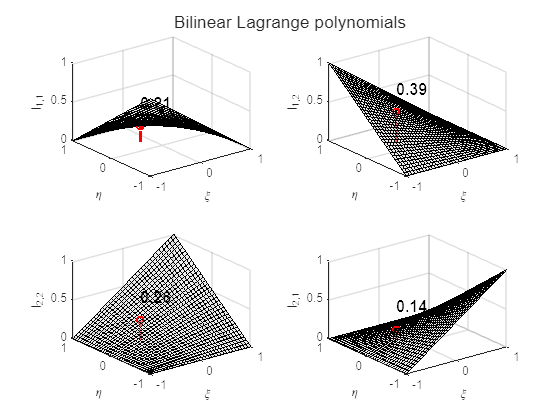

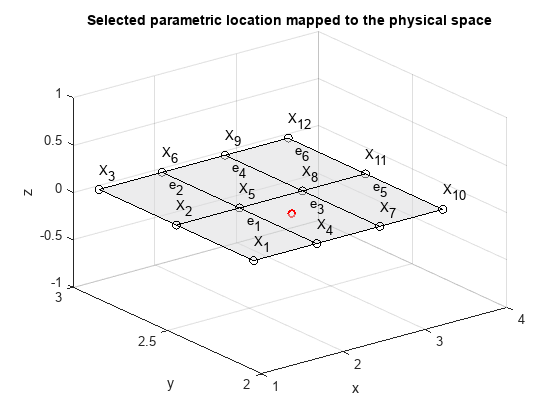

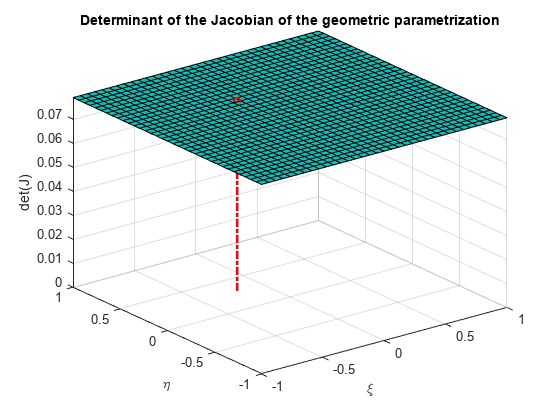

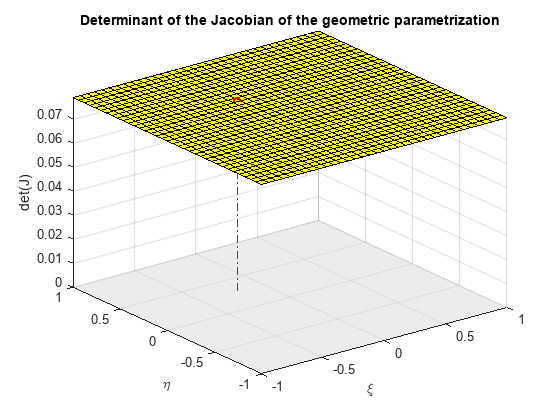

    figure,
    J_Q1 = jacobian([1, 0, 0; 0, 1, 0]*X_Q1);
    detJ_Q1 = det(J_Q1);
    fsurf(detJ_Q1, [-1 1 -1 1]);
    hold on;
    plot3(xi_, eta_, detJ_Q1(xi_, eta_), "ro", MarkerSize=5, LineWidth=1.5);
    plot3([xi_; xi_], [eta_; eta_], [0; detJ_Q1(xi_, eta_)], "-.r", ...
        MarkerSize=5, LineWidth=2);
    xlabel("\xi");
    ylabel("\eta");
    zlabel("det(J)");
    hold off;
    title("Determinant of the Jacobian of the geometric parametrization");

Display the determinant of the Jacobian at the chosen parametric location

    figure,
    J_Q1 = jacobian([1, 0, 0; 0, 1, 0]*X_Q1);
    detJ_Q1 = det(J_Q1);
    fsurf(detJ_Q1, [-1 1 -1 1]);
    hold on;
    fsurf(0, [-1 1 -1 1], FaceColor=[217, 218, 219]./255, FaceAlpha=0.5, ...
        LineStyle="none");
    plot3(xi_, eta_, detJ_Q1(xi_, eta_), "ro", MarkerSize=5, LineWidth=1.5);
    plot3([xi_; xi_], [eta_; eta_], [0; detJ_Q1(xi_, eta_)], "-.r", ...
        MarkerSize=5);
    xlabel("\xi");
    ylabel("\eta");
    zlabel("det(J)");
    hold off;
    title("Determinant of the Jacobian of the geometric parametrization");

end

### **Display a two-dimensional biquadratic mesh along with the geometric mapping and the determinant of the Jacobian at a selected parametric location **

function t = plotBiquadraticQuadrilateralMeshAndGeometryMapping ...
    (xi_, eta_, el, lij_Q2, msh, numVertices, ij)

**Function description**

Plots a graph displaying the basis functions and their values in the chosen parametric location corresponding to a two-dimensional biquadratic quadrilateral mesh. Moreover, the mapping and the determinant of the Jacobian for the selected parametric location is displayed on the physical space .

**               Input :**

        `xi_`, `eta_` : The selected parametric locations on the element

                    `el` : Selected element in the mesh

            `lij_Q2` : The two-dimensional biquadratic Lagrange Polynomials in the parametric space

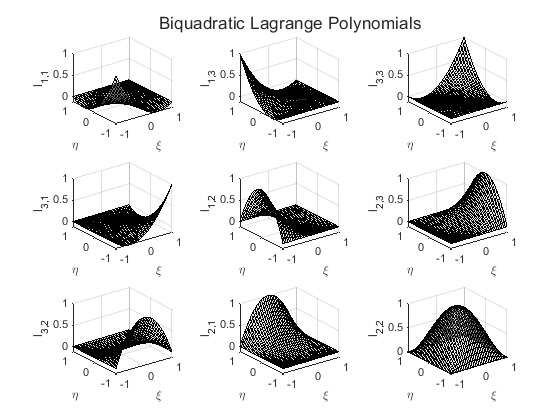

                  `msh` : A two-dimensional nine-noded mesh as a structure with the following fields:

                                `.nodes` : Number of nodes in the two-dimensional nine-noded mesh

                          `.elements` : Number of elements in the two-dimensional nine-noded mesh

  `numVertices` : Number of vertices in the biquadratic quadrilateral mesh

                    `ij` : Legend entries for the plot which should be an array with nine elements

**           Output :**

                     `t` : Handle to the tiledlayout graphical object

**Function implementation**

Read input

if ~ismember(el, 1:numel(msh.elements(:, 1)))
    error("The selected element does not belong to the provided mesh");
end

Set-up the geometric interpolation

    syms X_Q2(xi, eta)
    X_Q2(xi, eta) = transpose([lij_Q2{:}]*msh.nodes(msh.elements(el, :), 1:3));

Display the biquadratic Lagrange Polynomials evaluated at the selected parametric location

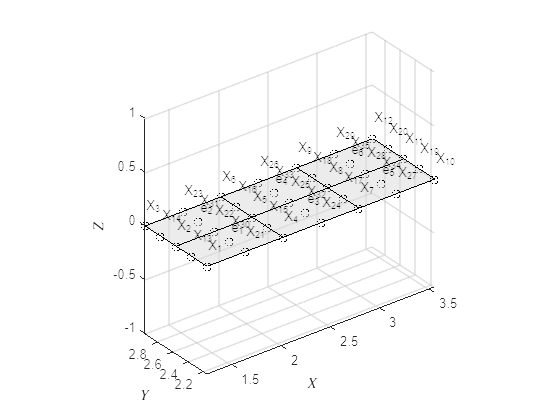

    t = tiledlayout(3, 3);
    for ii = 1:numel(lij_Q2)
        nexttile
        fsurf(lij_Q2{ii}, [-1 1 -1 1], FaceColor=[217, 218, 219]./255, FaceAlpha=0.5);

        hold on;
        plot3(xi_, eta_, lij_Q2{ii}(xi_, eta_), "ro", MarkerSize=5, LineWidth=1.5);
        plot3([xi_; xi_], [eta_; eta_], [0; lij_Q2{ii}(xi_, eta_)], "-.r", MarkerSize=5, ...
            LineWidth=2);
        text(xi_, eta_, lij_Q2{ii}(xi_, eta_) + 0.3, num2str(double(lij_Q2{ii}(xi_, eta_))), ...
            FontSize=12, FontWeight="bold");
        hold off;
        xlabel("\xi")
        ylabel("\eta")
        zlabel(sprintf("l_{%s}", num2str(ij(ii))))
    end
    title(t, "Biquadratic Lagrange polynomials");

Display the physical location at the selected element

    figure,
    plotMesh2d(msh, numVertices, true);
    hold on;
    X_ = X_Q2(xi_, eta_);
    plot3(X_(1, 1), X_(2, 1), X_(3, 1), "ro", MarkerSize=5, LineWidth=1.5);
    xlabel("x")
    ylabel("y")
    zlabel("z")
    hold off;
    title("Selected parametric location mapped to the physical space");

Display the determinant of the Jacobian at the chosen parametric location

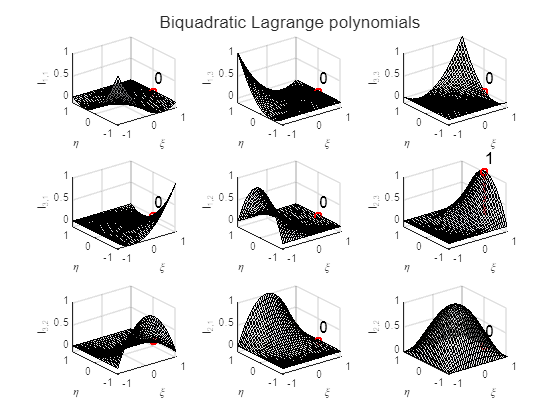

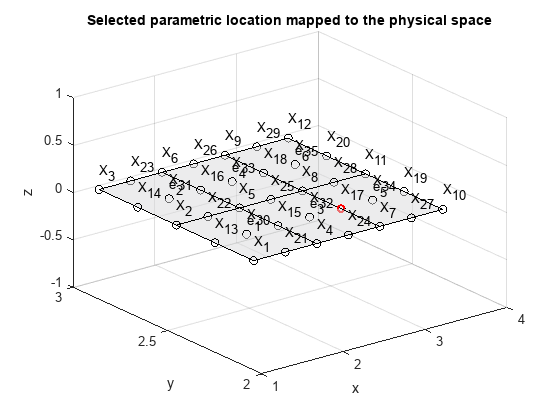

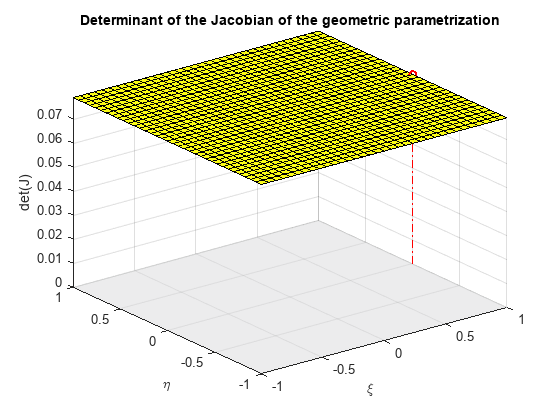

    figure,
    J_Q2 = jacobian([1, 0, 0; 0, 1, 0]*X_Q2);

    detJ_Q2 = det(J_Q2);
    fsurf(detJ_Q2, [-1 1 -1 1]);
    hold on;
    fsurf(0, [-1 1 -1 1], FaceColor=[217, 218, 219]./255, FaceAlpha=0.5, ...
        LineStyle="none");
    plot3(xi_, eta_, detJ_Q2(xi_, eta_), "ro", MarkerSize=5, LineWidth=1.5);
    plot3([xi_; xi_], [eta_; eta_], [0; detJ_Q2(xi_, eta_)], "-.r", MarkerSize=5);
    xlabel("\xi");
    ylabel("\eta");
    zlabel("det(J)");
    hold off;
    title("Determinant of the Jacobian of the geometric parametrization");

end